% Set the size of the matrix
rows = 7;
cols = 7;

% Set the density of non-zero elements (adjust as needed)
density = 0.4;

% Generate the random sparse matrix
M_k = sprand(rows, cols, density);

% Set the diagonal elements to non-zero values
diagonal_values = rand(rows, 1);
M_k = M_k + spdiags(diagonal_values, 0, rows, cols);

% Display the sparse matrix
disp(M_k);

   (1,1)       0.8907
   (5,1)       0.6808
   (7,1)       0.3125
   (1,2)       0.3335
   (2,2)       1.4494
   (2,3)       0.7118
   (3,3)       1.2486
   (5,3)       0.9232
   (1,4)       0.6927
   (4,4)       0.3264
   (3,5)       0.6330
   (4,5)       0.5293
   (5,5)       0.5499
   (3,6)       0.9300
   (6,6)       0.3888
   (7,6)       0.6939
   (1,7)       0.2038
   (2,7)       0.1669
   (4,7)       0.6265
   (5,7)       0.1528
   (6,7)       0.4057
   (7,7)       0.8968



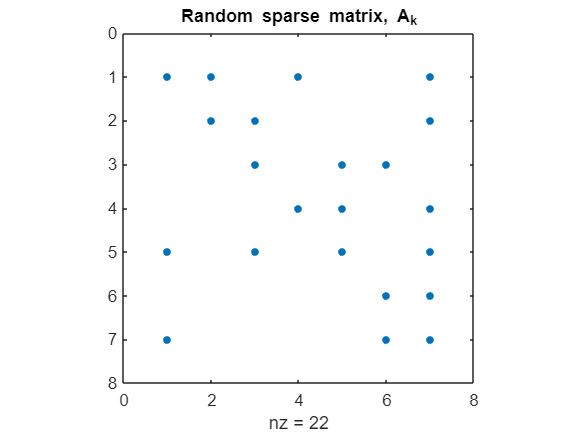

spy(M_k);
title("Random sparse matrix, A_k")

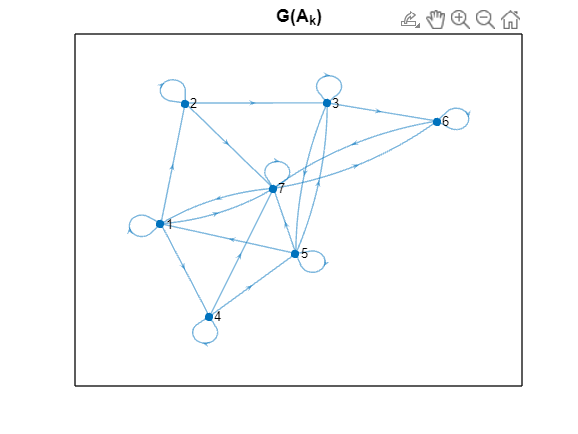

plot(digraph(M_k));
title("G(A_k)")

% Inverse of M_k
inv_M_k = inv(M_k);
disp(inv_M_k);

   (1,1)      -0.1229
   (2,1)      -0.4449
   (3,1)       0.8537
   (4,1)       1.7505
   (5,1)      -1.3428
   (6,1)      -0.2321
   (7,1)       0.2224
   (1,2)       0.0283
   (2,2)       0.7923
   (3,2)      -0.1964
   (4,2)      -0.4028
   (5,2)       0.3090
   (6,2)       0.0534
   (7,2)      -0.0512
   (1,3)       1.1390
   (2,3)       1.4791
   (3,3)      -2.5284
   (4,3)      -1.5704
   (5,3)       3.4076
   (6,3)       2.1507
   (7,3)      -2.0609
   (1,4)       0.2609
   (2,4)       0.9440
   (3,4)      -1.8114
   (4,4)      -0.6511
   (5,4)       2.8493
   (6,4)       0.4926
   (7,4)      -0.4720
   (1,5)      -1.5623
   (2,5)      -2.6114
   (3,5)       4.6543
   (4,5)       2.4345
   (5,5)      -4.8469
   (6,5)      -2.9499
   (7,5)       2.8267
   (1,6)     -15.1371
   (2,6)     -15.9560
   (3,6)      28.4899
   (4,6)      22.1290
   (5,6)     -33.8303
   (6,6)     -15.2244
   (7,6)      17.0536
   (1,7)       6.9546
   (2,7)       6.9577
   (3,7)     -12.5740
   (4,7)  

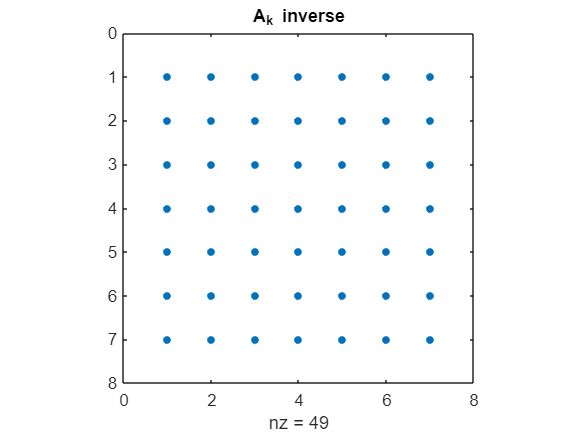

spy(inv_M_k);
title("A_k inverse")

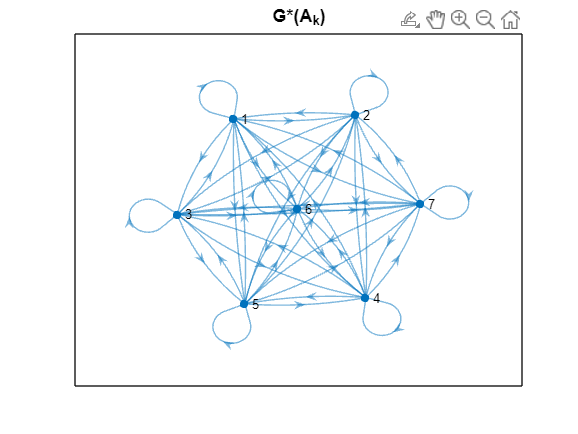

plot(digraph(inv_M_k));
title("G*(A_k)")

% Extract the diagonal elements as a column vector
%diagonal_vector = spdiags(M_k, 0);

% Convert the diagonal vector to a diagonal matrix
%diagonal_matrix = spdiags(diagonal_vector, 0, size(M_k, 1), size(M_k, 2));

% Display the diagonal matrix
%disp(diagonal_matrix);
%spy(diagonal_matrix);

% Extract the upper triangular matrix
upper_triangular_matrix = triu(M_k);

% Take the sparsity pattern
rand_upper_triangular_matrix = sprand(upper_triangular_matrix);

% Display the upper triangular matrix
disp(rand_upper_triangular_matrix);

   (1,1)       0.6761
   (1,2)       0.8284
   (2,2)       0.1101
   (2,3)       0.2792
   (3,3)       0.7676
   (1,4)       0.2161
   (4,4)       0.0341
   (3,5)       0.4366
   (4,5)       0.9369
   (5,5)       0.2621
   (3,6)       0.5697
   (6,6)       0.3596
   (1,7)       0.0268
   (2,7)       0.5004
   (4,7)       0.8270
   (5,7)       0.2590
   (6,7)       0.0459
   (7,7)       0.2465



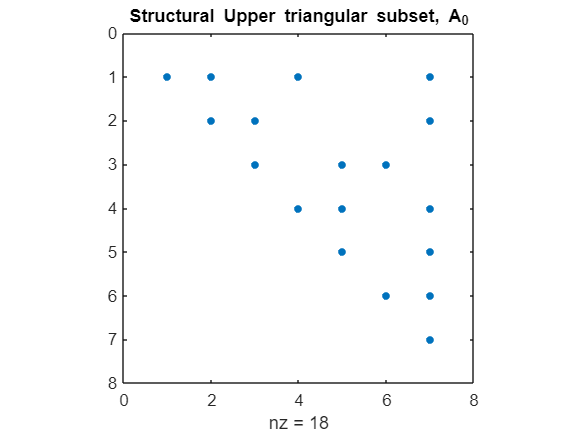

spy(rand_upper_triangular_matrix);
title("Structural Upper triangular subset, A_0")

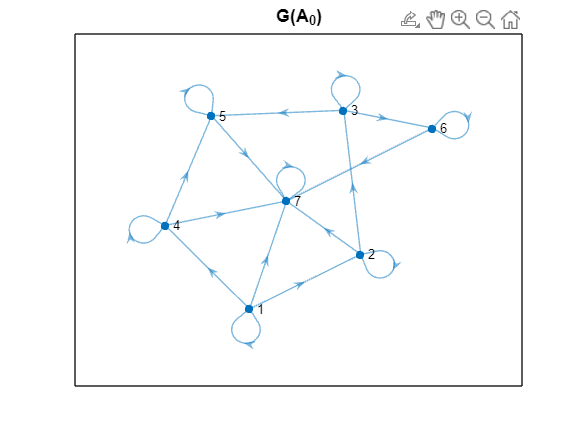

plot(digraph(rand_upper_triangular_matrix));
title("G(A_0)")

% Compute Exact Map with diagonal A_0
%N = inv_M_k * diagonal_matrix;
%disp(N);
%spy(N);

% Compute Exact Map with Upper Triangular A_0
N = inv_M_k * rand_upper_triangular_matrix;
disp(N);

   (1,1)      -0.0831
   (2,1)      -0.3008
   (3,1)       0.5772
   (4,1)       1.1836
   (5,1)      -0.9079
   (6,1)      -0.1570
   (7,1)       0.1504
   (1,2)      -0.0987
   (2,2)      -0.2813
   (3,2)       0.6856
   (4,2)       1.4058
   (5,2)      -1.0784
   (6,2)      -0.1864
   (7,2)       0.1786
   (1,3)       0.8823
   (2,3)       1.3566
   (3,3)      -1.9958
   (4,3)      -1.3180
   (5,3)       2.7020
   (6,3)       1.6658
   (7,3)      -1.5963
   (1,4)      -0.0177
   (2,4)      -0.0640
   (3,4)       0.1227
   (4,4)       0.3560
   (5,4)      -0.1931
   (6,4)      -0.0334
   (7,4)       0.0320
   (1,5)       0.3322
   (2,5)       0.8457
   (3,5)      -1.5810
   (4,5)      -0.6575
   (5,5)       2.8867
   (6,5)       0.6272
   (7,5)      -0.6010
   (1,6)      -4.7936
   (2,6)      -4.8943
   (3,6)       8.8031
   (4,6)       7.0618
   (5,6)     -10.2223
   (6,6)      -4.2487
   (7,6)       4.9575
   (1,7)       0.8415
   (2,7)       1.4717
   (3,7)      -2.1599
   (4,7)  

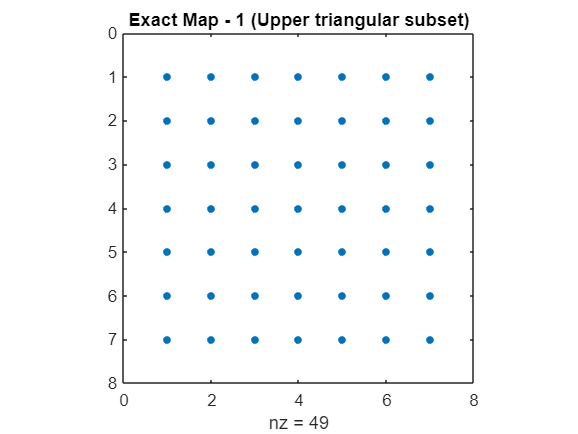

spy(N);
title("Exact Map - 1 (Upper triangular subset)")

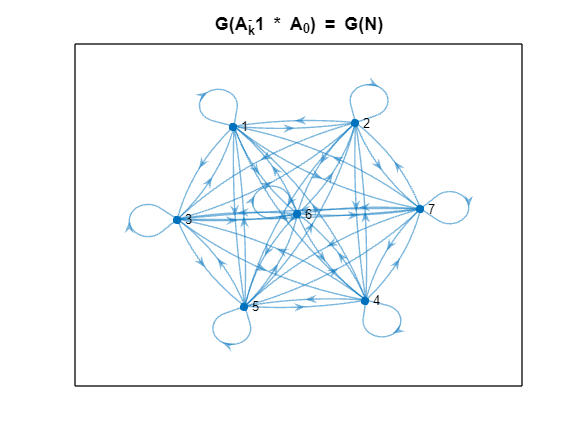

plot(digraph(N));
title("G(A_k^-1 * A_0) = G(N)")

% Compute SAM with Upper Triangular A_0
% Preprocess the sparsity pattern (here, we use patt(A_0))
[I,J] = find(upper_triangular_matrix);
findJ = sparse(I,J,1);
PP = logical(findJ);
PP2 = logical(sparse(double(PP)*double(PP))); % Taking powers of A_0 as apriori sparsity pattern for the map
nnzMM = nnz(PP2);
rowM = zeros(2*nnzMM,1);
colM = zeros(2*nnzMM,1);
valM = zeros(2*nnzMM,1);

% Compute SAM
for j = 1:cols
    % Initialize these later for efficiency...
    nz_M{j} = find(PP(:,j));
    nnz_M(j) = length(nz_M{j});
    nz_LS{j} = find(PP2(:,j));
    nnz_LS(j) = length(nz_LS{j});
end

max_col = max(nnz_M);
max_row = max(nnz_LS);
A_hat = zeros(max_row,max_col);
M_sam = zeros(max_row,1);
cntrM = 0;
for j = 1:cols
    A_hat(1:nnz_LS(j),1:nnz_M(j)) = M_k(nz_LS{j},nz_M{j});
    %[rC,cC] = size(A_hat(1:nnz_LS(j),1:nnz_M(j)));
    M_sam(1:nnz_M(j)) = A_hat(1:nnz_LS(j),1:nnz_M(j))\upper_triangular_matrix(nz_LS{j},j);
    rowM(cntrM+1:cntrM+nnz_M(j)) = nz_M{j};
    colM(cntrM+1:cntrM+nnz_M(j)) = j;
    valM(cntrM+1:cntrM+nnz_M(j)) = M_sam(1:nnz_M(j));
    cntrM = cntrM+nnz_M(j);
end
MM = sparse(rowM(1:cntrM),colM(1:cntrM),valM(1:cntrM));

disp(MM);

   (1,1)       1.0000
   (2,2)       1.0000
   (2,3)       0.0000
   (3,3)       1.0000
   (4,4)       1.0000
   (3,5)      -0.0000
   (4,5)      -0.0000
   (5,5)       1.0000
   (3,6)       0.0000
   (6,6)       1.0000
   (1,7)      -0.0000
   (2,7)      -0.0000
   (4,7)       0.0000
   (5,7)       0.0000
   (6,7)      -0.0000
   (7,7)       1.0000



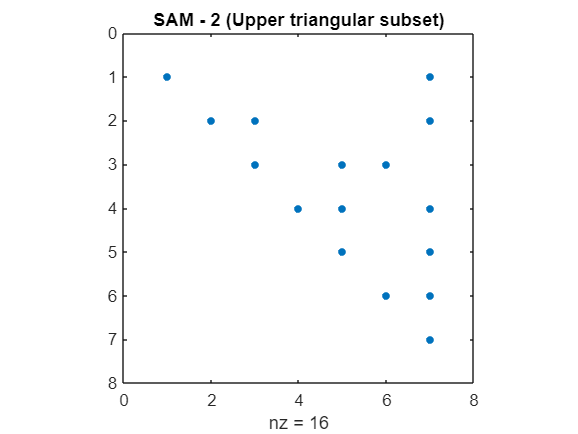

spy(MM);
title("SAM - 2 (Upper triangular subset)");

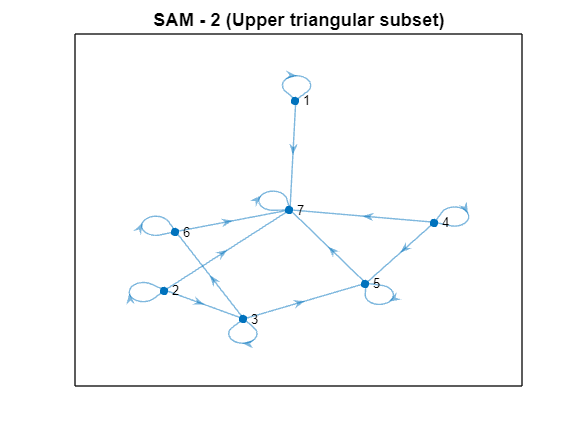

plot(digraph(MM));
title("SAM - 2 (Upper triangular subset)");

% Compare exact map and SAM

condest(M_k)

ans = 426.2595

condest(upper_triangular_matrix)

ans = 20.2729


condest(N)

ans = 5.8508e+03

condest(MM)

ans = 1.0000

% % Extract the lower triangular matrix
% lower_triangular_matrix = tril(M_k);
% 
% % Take the sparsity pattern
% rand_lower_triangular_matrix = sprand(lower_triangular_matrix);
% 
% % Display the upper triangular matrix
% disp(rand_lower_triangular_matrix);
% spy(rand_lower_triangular_matrix);
% title("Lower triangular subset, A_0")
% plot(digraph(rand_lower_triangular_matrix));
% title("G(A_0)")

% % Compute Exact Map with Lower Triangular A_0
% N = inv_M_k * rand_lower_triangular_matrix;
% disp(N);
% spy(N);
% title("Exact Map - 2 (Lower triangular subset)")
% plot(digraph(N));
% title("G(A_k^-1 * A_0) = G(N)")

% % Extract the tridiagonal band from A_k
% B = spdiags(M_k, [-1 0 1]);
% S = spdiags(B, [-1 0 1], rows, cols);
% 
% % Take the sparsity pattern
% rand_S = sprand(S);
% 
% disp(rand_S)
% spy(rand_S)
% title("Tridiagonal band subset, A_0")
% plot(digraph(rand_S));
% title("G(A_0)")

% % Compute Exact Map with Tridiagonal A_0
% N = inv_M_k * rand_S;
% disp(N);
% spy(N);
% title("Exact Map - 3 (Tridiagonal subset)")
% plot(digraph(N));
% title("G(A_k^-1 * A_0) = G(N)")